syms M m1 m2 l1 l2 g F t1 t2 x x_ t1_ t2_;

X_dotdot =(F - m1*g*t1 - m2*g*t2)/M;
t1_dotdot = (F - m1*g*t1 - m2*g*t2 - M*g*t1)/(M*l1);
t2_dotdot = (F - m1*g*t1 - m2*g*t2 - M*g*t2)/(M*l2);

X_states = [x x_ t1 t1_ t2 t2_];
X_eq = [x_ X_dotdot t1_ t1_dotdot t2_ t2_dotdot];

U_input = F;

A_ = zeros(length(X_eq), length(X_states)) + x;
for i = 1:length(X_eq)
    for j = 1:length(X_states)
        A_(i, j) = diff(X_eq(i), X_states(j));
    end
end
disp(A_)

$$\left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{g\,m_{1}}{M} & 0 & -\frac{g\,m_{2}}{M} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{M\,g+g\,m_{1}}{M\,l_{1}} & 0 & -\frac{g\,m_{2}}{M\,l_{1}} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{g\,m_{1}}{M\,l_{2}} & 0 & -\frac{M\,g+g\,m_{2}}{M\,l_{2}} & 0 \end{array}\right)$$


B_ = zeros(length(X_states), length(U_input)) + x;
for i = 1:length(U_input)
    for j = 1:length(X_eq)
        B_(j, i) = diff(X_eq(j), U_input(i));
    end
end
disp(B_)

$$\left(\begin{array}{c} 0\\ \frac{1}{M}\\ 0\\ \frac{1}{M\,l_{1}}\\ 0\\ \frac{1}{M\,l_{2}} \end{array}\right)$$


n = size(A_, 1); 

X0 = [0 ; 0.1 ; 10 ; 0.2 ; 5 ; 0.3];

M_v = 1000;
m1_v = 100;
m2_v = 100;
l1_v = 20;
l2_v = 10;
g_v = 9.8;

A = double(subs(A_, {M m1 m2 l1 l2 g}, {M_v m1_v m2_v l1_v l2_v g_v}))

A =          0    1.0000         0         0         0         0
         0         0   -0.9800         0   -0.9800         0
         0         0         0    1.0000         0         0
         0         0   -0.5390         0   -0.0490         0
         0         0         0         0         0    1.0000
         0         0   -0.0980         0   -1.0780         0



B = double(subs(B_, {M l1 l2}, {M_v l1_v l2_v}))

B = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000



R = 0.0001;
Q1 = 1;
Q2 = 100;
Q3 = 1;
Q4 = 100;
Q5 = 10;
Q6 = 10;

Q = diag([Q1, Q2, Q3, Q4, Q5, Q6]);

C_x = [1 0 0 0 0 0] 

C_x =      1     0     0     0     0     0


C_xt2 = [C_x; 0 0 0 0 1 0]

C_xt2 =      1     0     0     0     0     0
     0     0     0     0     1     0


C_xt1t2 = [C_x ; 0 0 1 0 0 0 ; 0 0 0 0 1 0]

C_xt1t2 =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0



D = 0;

[K, P, poles] = lqr(A, B, Q, R);

inputVariances = rand(1, 6)/2;
SigmaD = diag(inputVariances)

SigmaD =     0.0060         0         0         0         0         0
         0    0.1686         0         0         0         0
         0         0    0.0811         0         0         0
         0         0         0    0.3971         0         0
         0         0         0         0    0.1556         0
         0         0         0         0         0    0.2643



SigmaV = rand(1);

[L, P, poles] = lqr(A', C_x', SigmaD, SigmaV)

L =     3.0470    4.6241   -1.8498    1.0291   -1.2441   -0.0660


P =     0.5047    0.7660   -0.3064    0.1705   -0.2061   -0.0109
    0.7660    1.8317   -1.1041    0.3441   -0.6170   -0.2855
   -0.3064   -1.1041    2.5624    0.2429   -0.7654    0.7903
    0.1705    0.3441    0.2429    1.0283   -0.4091   -0.5537
   -0.2061   -0.6170   -0.7654   -0.4091    1.4465    0.0504
   -0.0109   -0.2855    0.7903   -0.5537    0.0504    1.4979


poles =   -0.1412 + 0.8772i
  -0.1412 - 0.8772i
  -0.4437 + 1.2698i
  -0.4437 - 1.2698i
  -0.9386 + 0.5611i
  -0.9386 - 0.5611i



A_lqg = [A-(B*K) B*K; zeros(n,n) A-(L'*C_x)]

A_lqg =          0    1.0000         0         0         0         0         0         0         0         0         0         0
   -0.1000   -1.1165   -1.2076   -0.0670   -1.0756    0.0390    0.1000    1.1165    0.2276    0.0670    0.0956   -0.0390
         0         0         0    1.0000         0         0         0         0         0         0         0         0
   -0.0050   -0.0558   -0.5504   -0.0034   -0.0538    0.0019    0.0050    0.0558    0.0114    0.0034    0.0048   -0.0019
         0         0         0         0         0    1.0000         0         0         0         0         0         0
   -0.0100   -0.1117   -0.1208   -0.0067   -1.0876    0.0039    0.0100    0.1117    0.0228    0.0067    0.0096   -0.0039
         0         0         0         0         0         0   -3.0470    1.0000         0         0         0         0
         0         0         0         0         0         0   -4.6241         0   -0.9800         0   -0.9800         0
         0         0    

B_lqg = [B; B]

B_lqg = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000
         0
    1.0000
         0
    0.0500


C_lqg =      1     0     0     0     0     0     0     0     0     0     0     0


C_lqg = [ C_x C_x]

C_lqg =      1     0     0     0     0     0     1     0     0     0     0     0


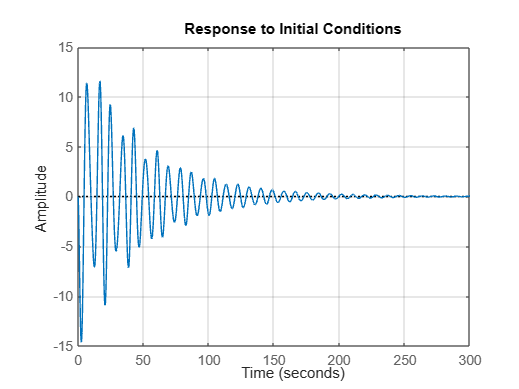


lqg_system_behaviour = ss(A_lqg, B_lqg, C_lqg, D);
figure(1)
initial(lqg_system_behaviour, [X0; zeros(n, 1)])
grid on